# Workplace cleaning

clear all
clc
clf
close all

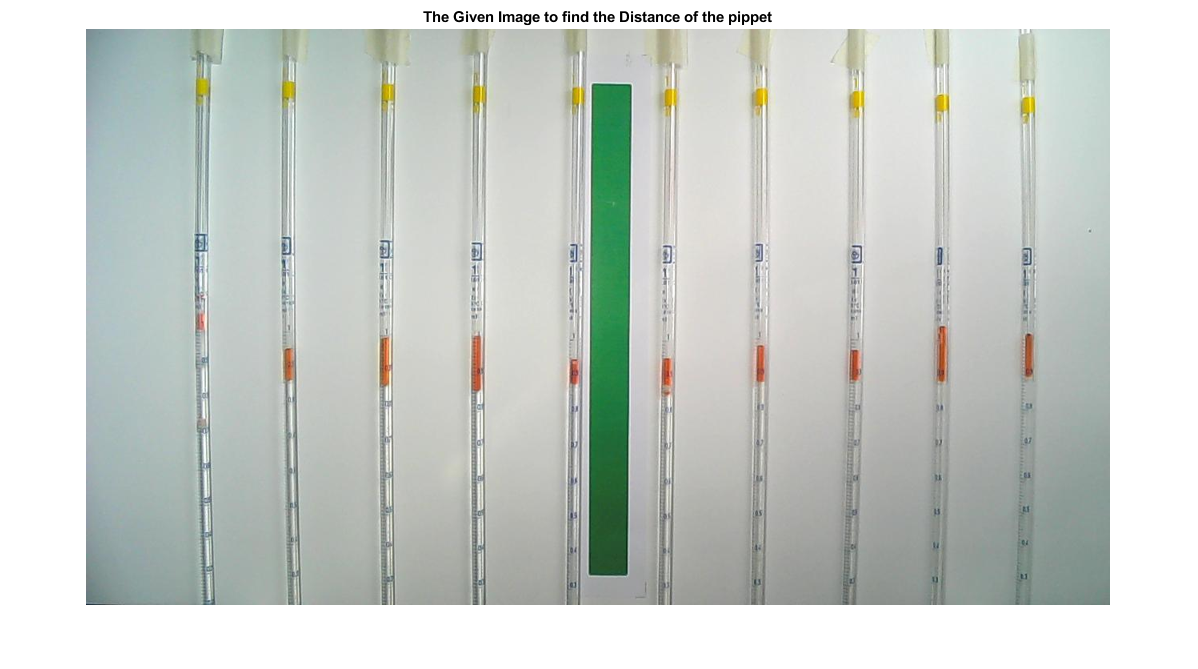

%importing Data
x=imresize(imread('0109.jpg'),[.8]);
figure(1) 
imshow(x)
title("The Given Image to find the Distance of the pippet")

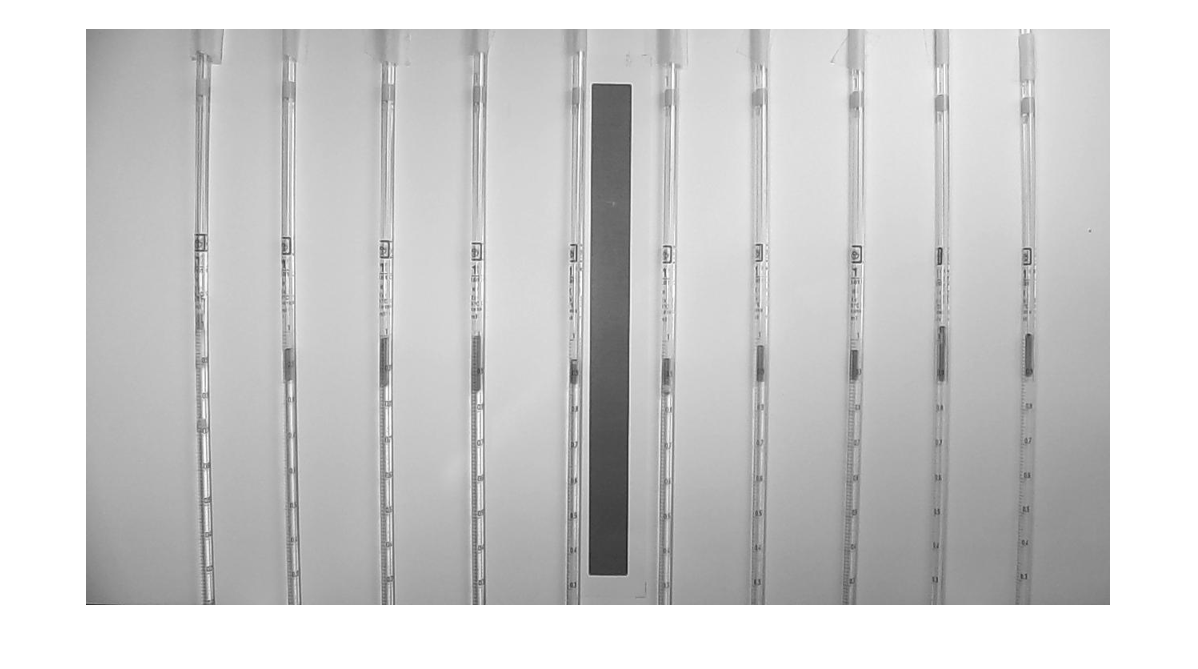


gray_im=rgb2gray(uint8(x));
imshow(gray_im);

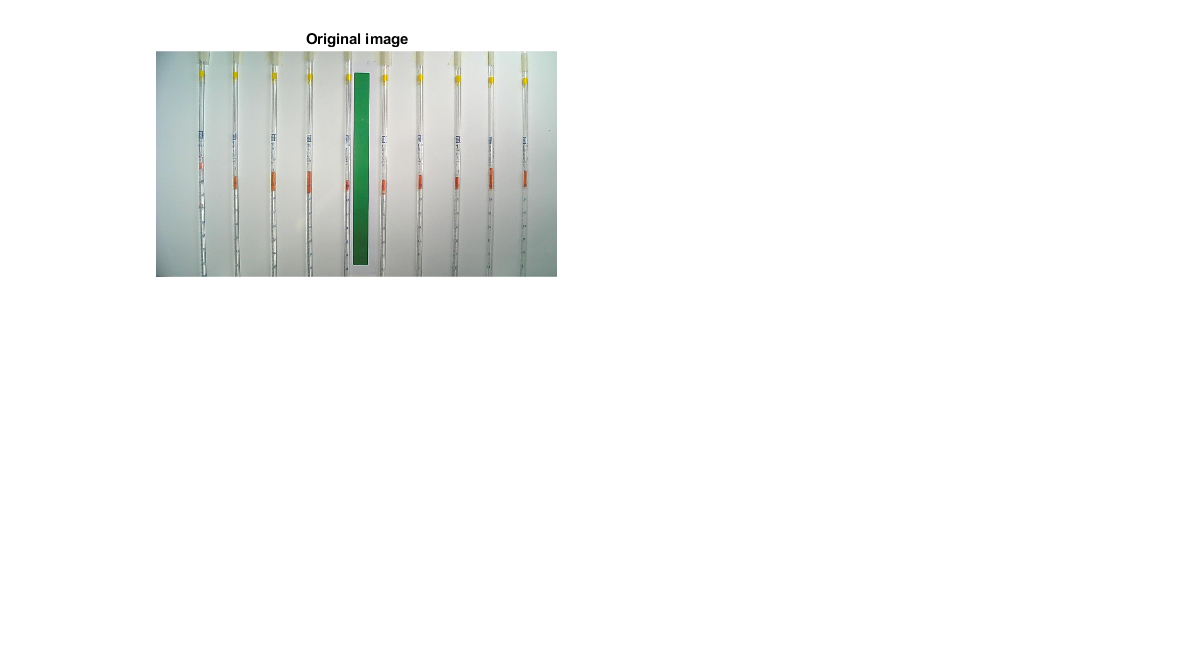


%%%image channel separation
red=x(:,:,1);
green=x(:,:,2);
blue=x(:,:,3);
%bw=imbinarize(gray_im);
% bw = imbinarize(gray_im,'adaptive','ForegroundPolarity','dark','Sensitivity',0.45);

%ploting original Image
subplot(2,2,1)
imshow(x)
title('Original image')

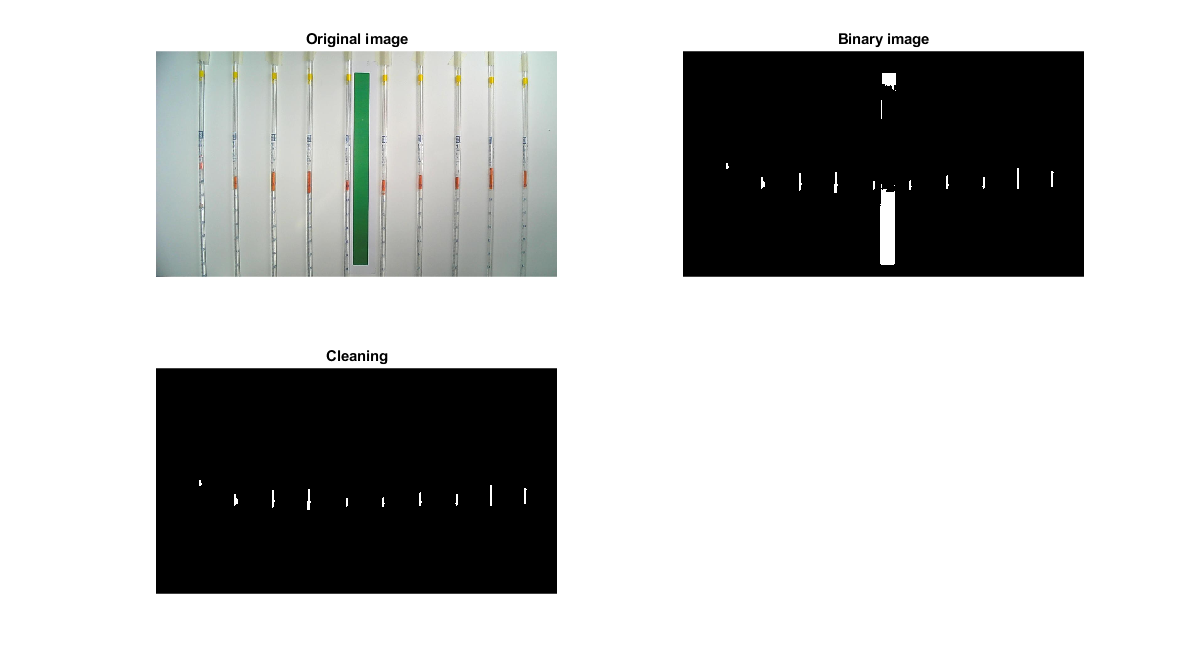

e = imbinarize(green,'adaptive','ForegroundPolarity','dark','Sensitivity',0.35);
f=green>105;
% imshow(e)
f=regionprops(e,'all');

g=bwareaopen(e,35);
se= strel('square',3);
h=imdilate(g,se);
i=1-h;
i1=bwareaopen(i,60);

subplot(2,2,2)
imshow(i1)
title('Binary image')
LB = 65;
UB = 700;
Iout = xor(bwareaopen(i1,LB),  bwareaopen(i1,UB));
subplot(2,2,3)
imshow(Iout);
title('Cleaning');


Iout1 = imfill(Iout,'holes');
[L,n]=bwlabel(Iout1);
j=regionprops(Iout1,'Centroid');
for i=1:length(j)
x_c(i)=j(i).Centroid(1);
y_c(i)=j(i).Centroid(2);

end
pos_x=x_c';
pos_y=y_c';
disp('Number of pippet is : ')

Number of pippet is : 


n

n = 10

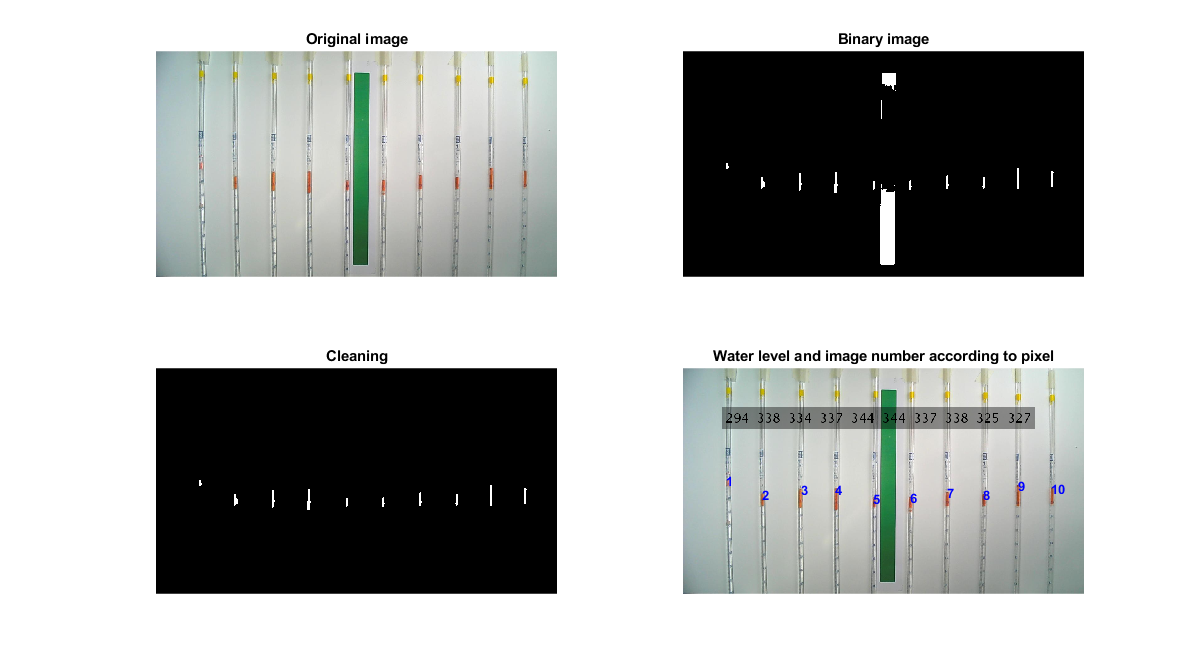

position=[100,100];

kk=insertText(x,position,num2str(ceil((y_c))),...
    'BoxOpacity',0.4,'FontSize',32,'BoxColor','black');
subplot(2,2,4)
imageHandle=imshow(kk);
title('Water level and image number according to pixel')

axesHandle = ancestor(imageHandle, 'axes');
hold(axesHandle, 'on')
%%test
s = regionprops(L, 'Extrema');
for k = 1:numel(s)
   e = s(k).Extrema;
   text(e(1,1), e(1,2), sprintf('%d', k), ...
      'Parent', axesHandle, ...
      'Clipping', 'on', ...
      'Color', 'b', ...
      'FontWeight', 'bold');
end